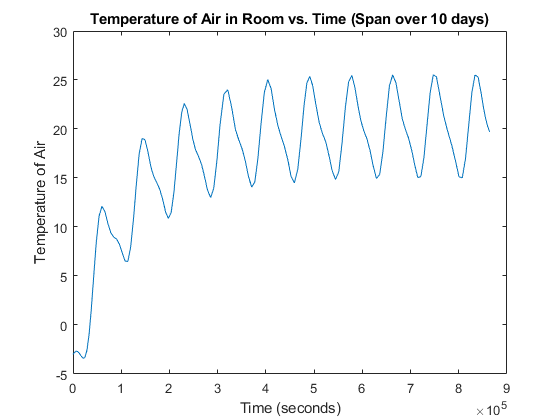

% QEA II - Project 1 (Passive Solar Tiny House for MA) %

% Values given to us%
T_out = -3; % Temperature outside
m = 250; % (in kg) V = 250 Liters, d = 1 cm^3 
c = 4200; % units: J/kg - K

% Specific Heat Capacity %
C_HeatStorage = m * c;

% Heat Transfer Coefficient (W/m^2-K)%
h_indoor = 15; % heat transfer coefficient for indoors
h_outdoor = 30; % heat transfer coefficient for outdoors 
h_window = 0.7; % heat transfer coefficient for double-panned windows 

% Thermal Conductivity (W/m-k) %
k_fginsulation = 0.04; % thermal conductivity of fiberglass insulation 
k_wall = 0.15; % thermal conductivity of insulated brick  
k_roof = 0.07; % thermal conductivity of concrete !!! need to change this to insulated concrete -> 0.07 - 0.33 values
k_floor = 0.07; % thermal conductivity of tile floor

% Thickness of Elements (m) % 
L_wall = 0.75; % thickness of wall 
L_roof = 1.5; % thickness of roof
L_floor = 1.0; % thickness of floor
L_window = 0.25; %thickness of window (curtain window)

% Surface Area of Elements (m^2)%
A_floor = 12.25; % area of *soon to be concrete* floor (3.5 x 3.5)
A_wall = 9; % area of brick wall (3 x 3)
A_roof = 12.25; % area of concrete roof (3.5 x 3.5)
A_window = 9; % area of window (3 x 3)

% Resistance of housing elements (K/W)% 
R_floor = (1/(h_indoor * A_floor)) + (L_floor/(k_floor * A_floor)) + (1/(h_outdoor * A_floor)) ; 
R_wall = (1/(h_indoor * A_wall)) + (L_wall/(k_wall * A_wall)) + (1/(h_outdoor * A_wall));
R_roof = (1/(h_indoor * A_roof)) + (L_roof/(k_roof * A_roof)) + (1/(h_outdoor * A_roof));
R_window = (1/(h_indoor * A_window)) + (1/(h_window * A_window)) + (1/(h_outdoor * A_window));

%Calculating total resistance of system (K/W)%
R_total = ((1/R_floor) + (1/R_wall) + (1/R_roof) + (1/R_window))^(-1); 

% Plotting and Solving ODE %
%Q_in = -361*cos((3.14*t)/(12*3600)) + 224*cos((3.14*t)/(6*3600)) + 210; % Temperature modeled as a function of time %
tspan = [0 86400*10];
[t, T] = ode45(@(t,T) (((T - T_out)/ R_total) - (-361*cos((3.14*t)/(12*3600)) + 224*cos((3.14*t)/(6*3600)) + 210)) / (-C_HeatStorage) , tspan, -3);
plot(t, T, '-');
title('Temperature of Air in Room vs. Time (Span over 10 days)');
xlabel('Time (seconds)');
ylabel('Temperature of Air');